load net1.mat

现在 SIM 用于对任何其他输入向量（如 [0.7; 1.2]）进行分类。此新点及原始训练集的绘图显示了网络的性能。为了将其与训练集区分开来，将其显示为红色。

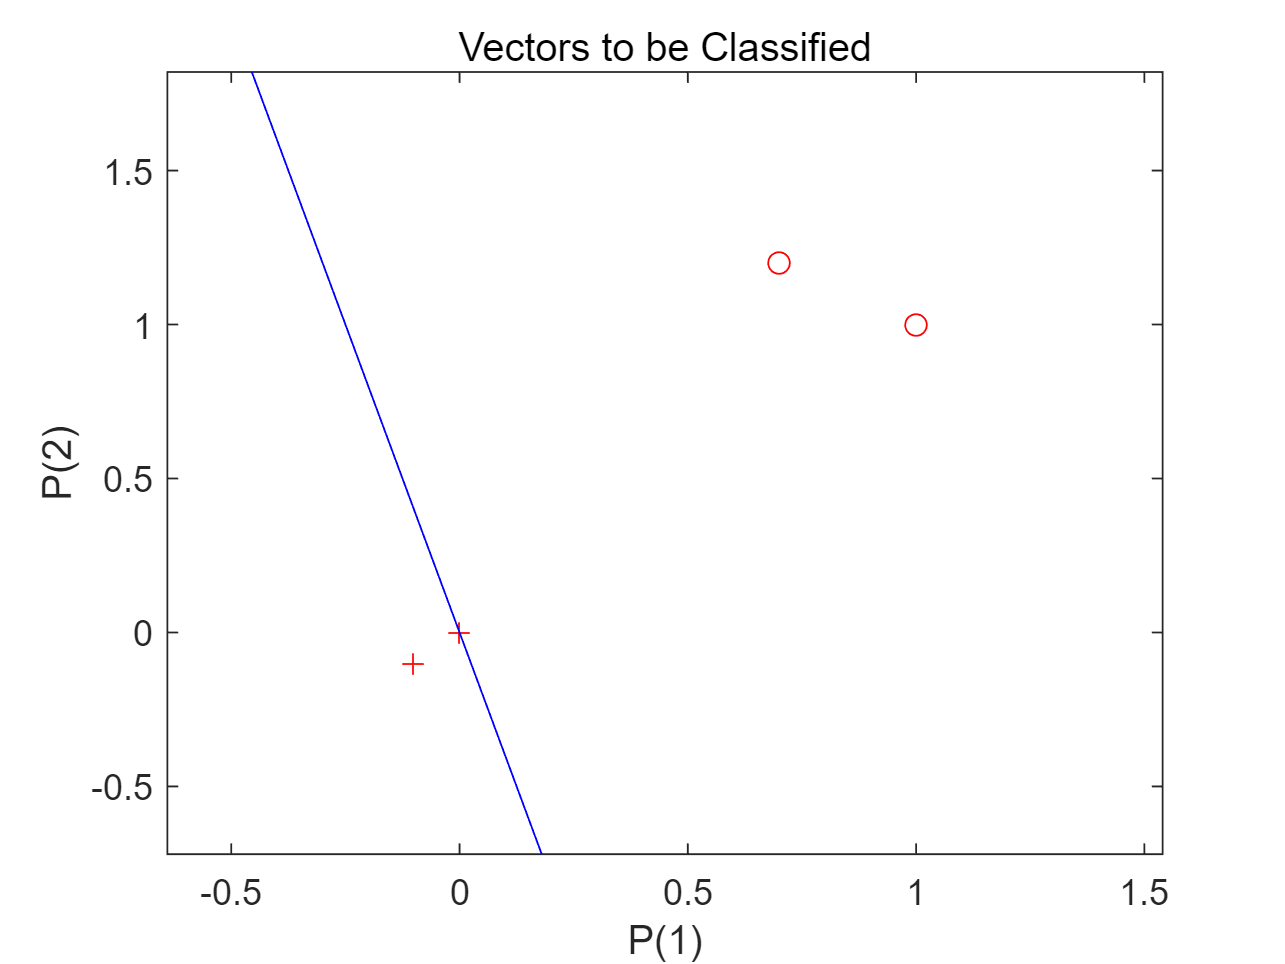

x = [0.7 -0.1 1 0; 1.2 -0.1 1 0];
y = net(x);
plotpv(x, y);
point = findobj(gca, 'type', 'line');
set(point, 'Color', 'red');
plotpc(net.IW{1}, net.b{1}); % 画出分割线